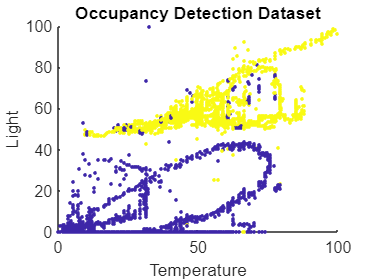

rng('default');  % Random seed for reproducibility

% Load Occupancy Detection Dataset
opts = detectImportOptions('datatraining_2.txt',"VariableNamingRule","preserve");
% Feature selection
opts.SelectedVariableNames = {'Var3', 'Var5','Var8'};
data = readtable('datatraining_2.txt',opts);
data = rmmissing(data);

% Convertion from table to array matrix
X1 = table2array(data(:,1));
X2 = table2array(data(:,2));
Y = table2array(data(:,3));

for i = 1:length(Y)
    if Y(i)==0
        Y(i)=-1;
    end
end

% Removing outliers
X1 = X1(X2<900);
X2 = X2(X2<900);
Y = Y(X2<900);

% Normalizing the features
X1 = 100*(X1 - min(X1)) / (max(X1)-min(X1));
X2 = 100*(X2 - min(X2)) / (max(X2)-min(X2));

% Plot of the dataset
figure
scatter(X1,X2,5,Y,'filled');
title('Occupancy Detection Dataset');
xlabel('Temperature');
ylabel('Light');

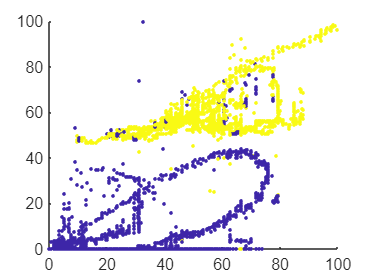



n = length(Y); % numero di punti  
p = 0.02; % frazione di punti etichettati

% sample generator with gaussian distribution
l = ceil(n*p); % numero di sample etichettati (occhio fallo intero)
samp=randperm(n,l);
indices=1:n;
X = [X1,X2];
y_tot = Y;
u=n-l;

% build the data
X_samp=X(samp,:);
X_unlabeled = X(setdiff(1:end,samp),:);
y_samp=y_tot(samp);
y_exact=y_tot(setdiff(1:end,samp));

%visualize the data
scatter(X(:,1),X(:,2),5,y_tot,'filled')

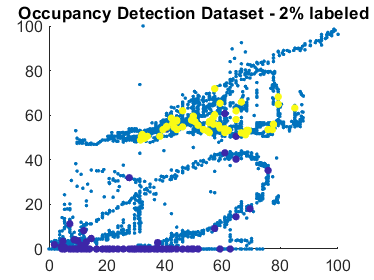

figure;
scatter(X(:,1),X(:,2),5,'filled')
hold on 
scatter(X_samp(:,1),X_samp(:,2),20,y_samp,'filled')
title('Occupancy Detection Dataset - 2% labeled')
hold off


%Calcolo distanze "utili", lab-nolab e nolab-lab
D_samp=pdist2(X_samp, X_unlabeled);

D=pdist2(X_unlabeled,X_unlabeled);

% Calcolo pesi exp(-x)
W_samp= exp(-D_samp);
W = exp(-D);

%Parameters for the gradient methods
y0 = zeros(u,1); %cioè delle etichette casuali per i dati no-lab 
eps = 1e-4; %tolleranza
maxit = 1000; %iterazioni max
%Choose the method to be tested
step_size=input('Choose step size:'); % regola per lo step_size

delta=0.5;   % per l'armijo rule

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%METODO DEL GRADIENTE CLASSICO
    
[y_GD, timeVec_GD, Norms_GD, accuracy_GD]= ...
    GD(maxit,eps,y0,y_samp,W,W_samp,step_size,y_exact,delta); 


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% BCGD with cyclic rule

[y_BCGDcyc, timeVec_BCGDcyc, Norms_BCGDcyc, accuracy_BCGDcyc] = ...
    BCGD_cyclic(y0,maxit,eps,y_samp,W,W_samp,step_size,y_exact,delta);

  

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% BCGD with randomized rule

[y_BCGDrand, timeVec_BCGDrand, Norms_BCGDrand, accuracy_BCGDrand] = ...
    BCGD_random(maxit,eps,y0,y_samp,W,W_samp,step_size,y_exact,delta);

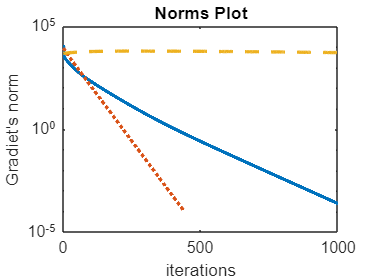



%PLOT THE RESULTS
figure(3)
semilogy(Norms_GD,LineWidth = 2)
hold on
semilogy(Norms_BCGDcyc,':',LineWidth = 2)
semilogy(Norms_BCGDrand,'--',LineWidth = 2)
hold off
title('Norms Plot')
xlabel('iterations')
ylabel("Gradiet's norm")

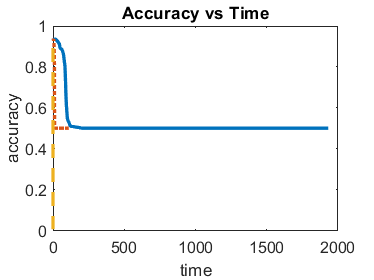


figure(4)
plot(timeVec_GD,accuracy_GD,LineWidth = 2)
hold on
plot(timeVec_BCGDcyc,accuracy_BCGDcyc,':',LineWidth = 2)
plot(timeVec_BCGDrand,accuracy_BCGDrand,'--',LineWidth = 2)
hold off
title('Accuracy vs Time')
xlabel('time')
ylabel('accuracy')

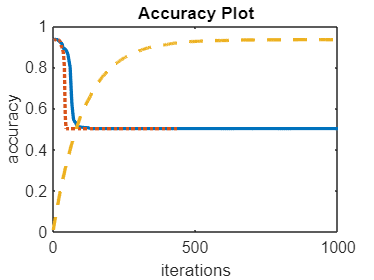


figure(5)
plot(accuracy_GD,LineWidth = 2)
hold on
plot(accuracy_BCGDcyc,':',LineWidth = 2)
plot(accuracy_BCGDrand,'--',LineWidth = 2)
hold off
title('Accuracy Plot')
xlabel('iterations')
ylabel('accuracy')

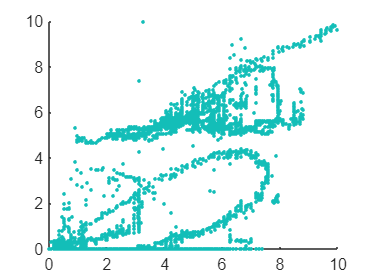


%visualize final data labeled
figure(6)
scatter(X_unlabeled(:,1),X_unlabeled(:,2),5,sign(y_GD),'filled')

figure(7)
scatter(X_unlabeled(:,1),X_unlabeled(:,2),5,sign(y_BCGDcyc),'filled')

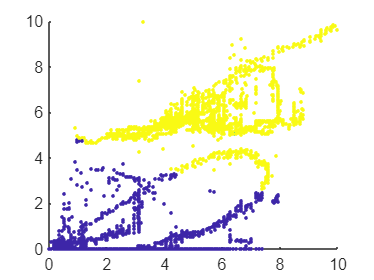

figure(8)
scatter(X_unlabeled(:,1),X_unlabeled(:,2),5,sign(y_BCGDrand),'filled')